read stats for every continent

analysis_AF = tdfread('../analysis_2020_08/lcc_AF.csv', ",");
analysis_AS = tdfread('../analysis_2020_08/lcc_AS.csv', ',');
analysis_EU = tdfread('../analysis_2020_08/lcc_EU.csv', ',');
analysis_NA = tdfread('../analysis_2020_08/lcc_NA.csv', ',');
analysis_OC = tdfread('../analysis_2020_08/lcc_OC.csv', ',');
analysis_SA = tdfread('../analysis_2020_08/lcc_SA.csv', ',');
analysis_MANY = tdfread('../analysis_2020_08/lcc_MANY.csv', ',');

extract LCC cov distributions ordered

lcc_cov_AF = sortrows(analysis_AF.largest_cc_coverage);
lcc_cov_AS = sortrows(analysis_AS.largest_cc_coverage);
lcc_cov_EU = sortrows(analysis_EU.largest_cc_coverage);
lcc_cov_NA = sortrows(analysis_NA.largest_cc_coverage);
lcc_cov_OC = sortrows(analysis_OC.largest_cc_coverage);
lcc_cov_SA = sortrows(analysis_SA.largest_cc_coverage);
lcc_cov_MANY = sortrows(analysis_MANY.largest_cc_coverage);

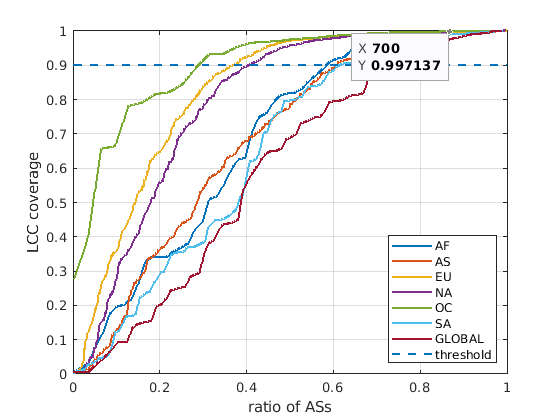

clf
max_len = length(lcc_cov_EU);
new_lcc_AF = norm_plot(max_len, lcc_cov_AF);
plot(new_lcc_AF, 'DisplayName', 'AF', "LineWidth",1.5)
hold on
new_lcc_AS = norm_plot(max_len, lcc_cov_AS);
plot(new_lcc_AS, 'DisplayName', 'AS', "LineWidth",1.5)
new_lcc_EU = norm_plot(max_len, lcc_cov_EU);
plot(lcc_cov_EU, 'DisplayName', 'EU', "LineWidth",1.5)
new_lcc_NA = norm_plot(max_len, lcc_cov_NA);
plot(new_lcc_NA, 'DisplayName', 'NA', "LineWidth",1.5)
new_lcc_OC = norm_plot(max_len, lcc_cov_OC);
plot(new_lcc_OC, 'DisplayName', 'OC', "LineWidth",1.5)
new_lcc_SA = norm_plot(max_len, lcc_cov_SA);
plot(new_lcc_SA, 'DisplayName', 'SA', "LineWidth",1.5)
new_lcc_MANY = norm_plot(max_len, lcc_cov_MANY);
plot(new_lcc_MANY, 'DisplayName', 'GLOBAL', "LineWidth",1.5)
plot(0.9*ones(max_len,1), 'DisplayName', 'threshold', "LineStyle","--", "LineWidth",1.5)
legend("Location","southeast")
xlim([0 max_len])
xticks([0:max_len/5:max_len])
xticklabels({'0', '0.2', '0.4', '0.6', '0.8', '1'})
grid on
xlabel("Ratio of ASs")
ylabel("LCC coverage")
hold off

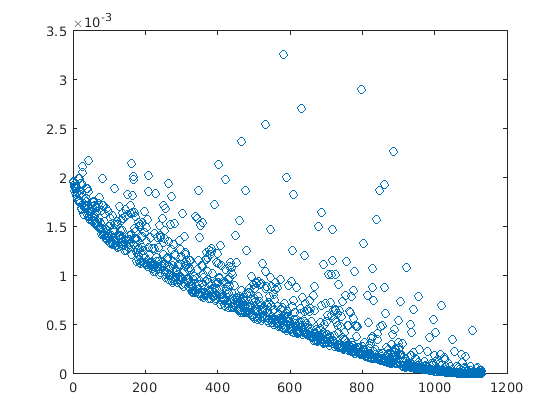

density_matrix = [analysis.ds_links analysis.density_lcc];
density_matrix = rmmissing(sortrows(density_matrix, 1));
plot(density_matrix(:,2), 'o');

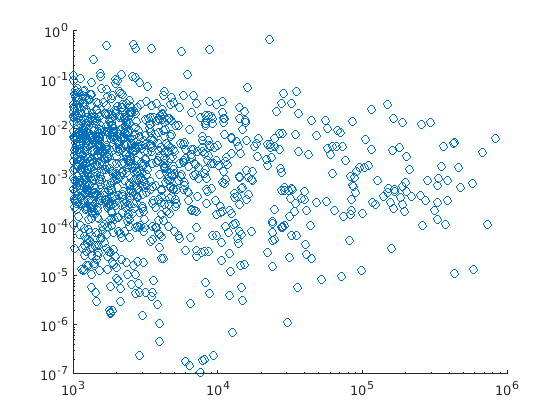

trans_nodes = rmmissing([analysis.ds_nodes analysis.transitivity_lcc]);
scatter(trans_nodes(:,1), trans_nodes(:,2));
set(gca,'xscale','log');
set(gca,'yscale','log');

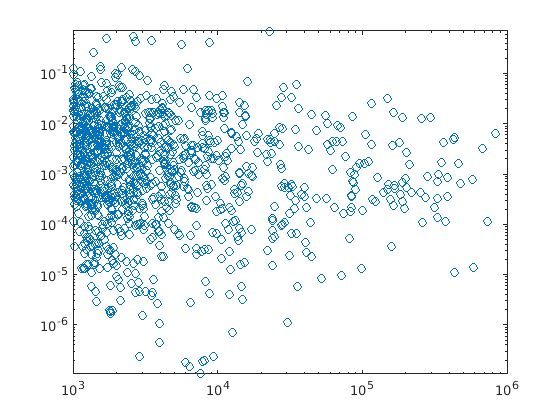

plot(trans_nodes(:,1), trans_nodes(:,2), 'o')
lsline
set(gca,'xscale','log');
set(gca,'yscale','log');

% lsline